## Open Loop Step Input Response

### The s-domain tranfer funciton

Example from: Radial Basis Function (RBF) Neural Network Control for Mechanical Systems - pg 63 - 66

The program of RBF supervisory control is chap3_1.m.


$$G(s) = \frac{1000}{s^2 + 50s + 2000}$$


clear; 
dt = 0.0001;        % sample time
t = 0:dt:0.5;

s = tf('s');
G = (1000) / (s^2 + 50*s + 2000)

G =
 
        1000
  -----------------
  s^2 + 50 s + 2000
 
Continuous-time transfer function.
Model Properties


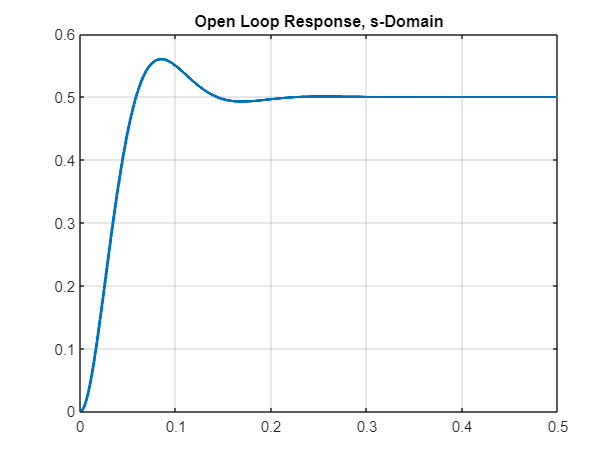


[x, t] = step(G, t);

plot(t, x, 'LineWidth', 2);
title('Open Loop Response, s-Domain')
grid on;

### Convert transfer function to z-domain

Gz = c2d(G, dt, 'tustin')     % convert to z-domain

Gz =
 
  2.494e-06 z^2 + 4.988e-06 z + 2.494e-06
  ---------------------------------------
           z^2 - 1.995 z + 0.995
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


Gz.variable = 'z^-1'            % inverse z-transform

Gz =
 
  2.494e-06 + 4.988e-06 z^-1 + 2.494e-06 z^-2
  -------------------------------------------
          1 - 1.995 z^-1 + 0.995 z^-2
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


[num, den] = tfdata(Gz, 'v')

num = 1.0e-05 *

    0.2494    0.4988    0.2494


den =     1.0000   -1.9950    0.9950


### Solving difference equation step by step

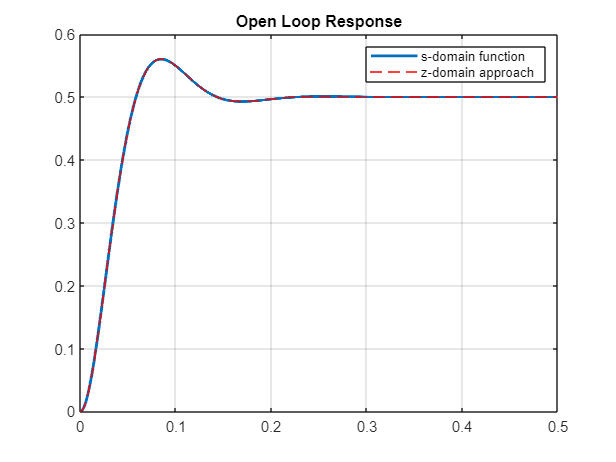

% output variable
y = zeros(size(t));

% step input
u = ones(size(t));
u(1) = 0;

% initial conditions
yk_1 = 0;
yk_2 = 0;
uk_1 = 0;
uk_2 = 0;

% solving difference equation
for i = 1:length(t)
    if i == 1
        uterms = num(1)*u(i) + num(2)*uk_1 + num(3)*uk_2;
        yterms = -den(2)*yk_1 - den(3)*yk_2;
        y(i) = uterms + yterms;
    elseif i == 2
        uterms = num(1)*u(i) + num(2)*u(i-1) + num(3)*uk_1;
        yterms = -den(2)*y(i-1) - den(3)*yk_1;
        y(i) = uterms + yterms;
    else
        uterms = num(1)*u(i) + num(2)*u(i-1) + num(3)*u(i-2);
        yterms = -den(2)*y(i-1) - den(3)*y(i-2);
        y(i) = uterms + yterms;
    end
end

hold on;
plot(t, y, 'r--')
legend('s-domain function', 'z-domain approach')
title('Open Loop Response')
grid on;
hold off;

## Closed Loop Step Response

Response with PD Controller 

### The s-domain tranfer funciton

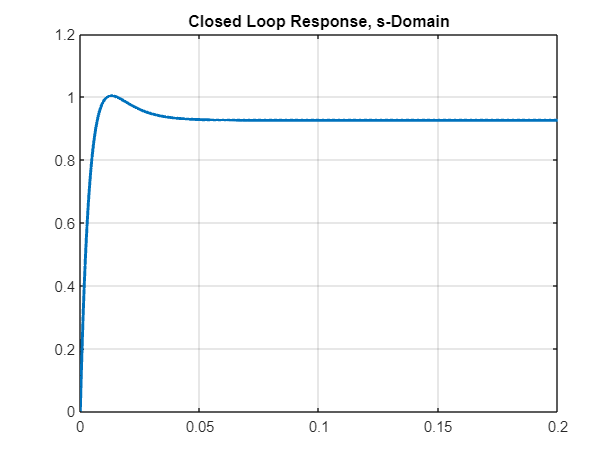

% PD Parameters
kp = 25;
kd = 0.3;

C = pid(kp, 0, kd);         % PD Controller

t = 0:dt:0.2;

G_cl = feedback(C*G, 1);     % Closed Loop Transfer Function
[x, t] = step(G_cl, t);      % Step Response of Closed Loop
plot(t, x, 'LineWidth', 2);
title('Closed Loop Response, s-Domain')
grid on;

### Solving difference equation step by step

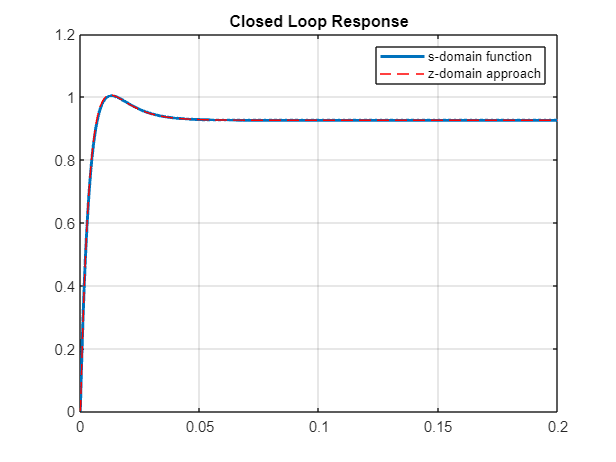

% output variable
y = zeros(size(t));

% step input
u = ones(size(t));
u(1) = 0;

ek_1 = 0;               % intial value of error
e = zeros(size(t));     % error vector
up = zeros(size(t));    % controller output vector

% solving difference equation
for i = 1:length(t)
    if i == 1
        e(i) = u(i) - yk_1;     % error
        up(i) = kp*e(i) + kd*((e(i) - ek_1)/dt);    % PD Controller
        uterms = num(1)*up(i) + num(2)*uk_1 + num(3)*uk_2;
        yterms = -den(2)*yk_1 - den(3)*yk_2;
        y(i) = uterms + yterms;
    elseif i == 2
        e(i) = u(i) - y(i-1);     % error
        up(i) = kp*e(i) + kd*((e(i) - e(i-1))/dt);    % PD Controller
        uterms = num(1)*up(i) + num(2)*up(i-1) + num(3)*uk_1;
        yterms = -den(2)*y(i-1) - den(3)*yk_1;
        y(i) = uterms + yterms;
    else
        e(i) = u(i) - y(i-1);     % error
        up(i) = kp*e(i) + kd*((e(i) - e(i-1))/dt);    % PD Controller
        uterms = num(1)*up(i) + num(2)*up(i-1) + num(3)*up(i-2);
        yterms = -den(2)*y(i-1) - den(3)*y(i-2);
        y(i) = uterms + yterms;
    end
end


hold on;
plot(t, y, 'r--')
legend('s-domain function', 'z-domain approach')
title('Closed Loop Response')
grid on;
hold off;

References: 

- [4 Ways to Implement a Transfer Function in Code | Control Systems in Practice](https://www.youtube.com/watch?v=nkq4WkX7CFU&t=923s)